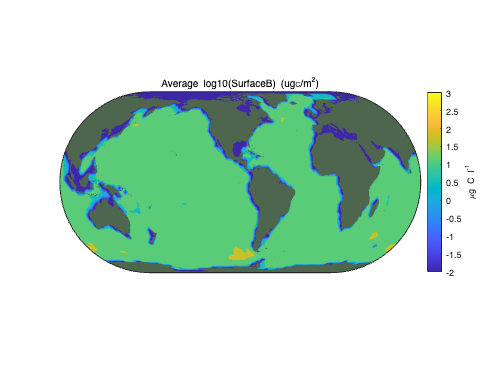

%
% Plot the output of a global simulation
%
sField = "B";
sProjection = 'eckert4';

field = calcIntegrateGlobal(sim, eval( strcat('sim.',sField)), true); % Calc global average of field

clf
panelGlobal(sim.x, sim.y, log10(field), ...
    [-2,3],sTitle = strcat('Average log10(Surface ',sField,') (ug_C/m^2)'), sProjection=sProjection);

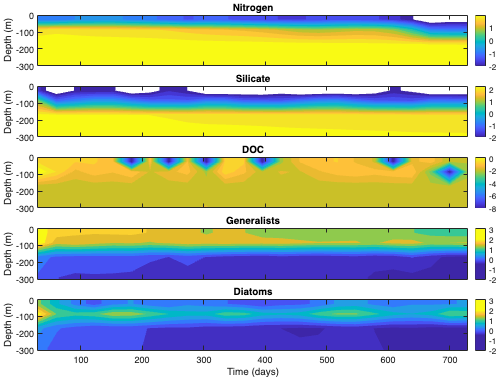


latitude = 0;
longitude = 5;

plotWatercolumnTime(sim, latitude, longitude, depthMax=300);

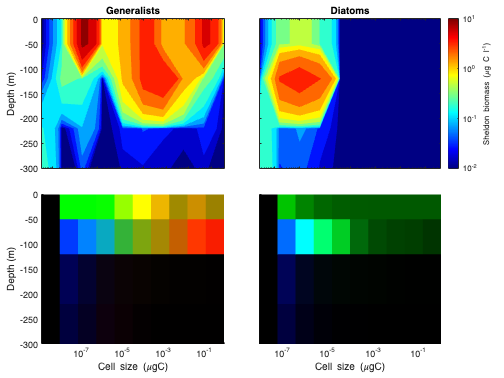

tDay = 195;
plotWatercolumn(sim, tDay, latitude, longitude, depthMax=300)%%

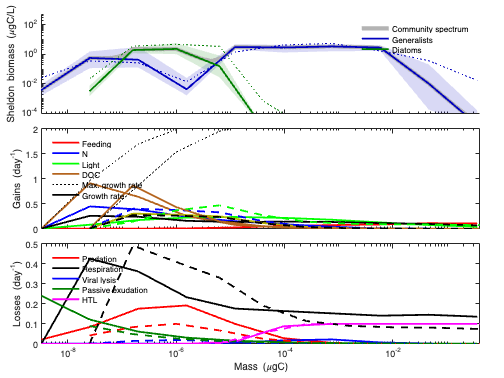


iDepth = 2;
         
plotSizespectrum(sim, tDay,iDepth, latitude, longitude);